# **上路+下路优化**

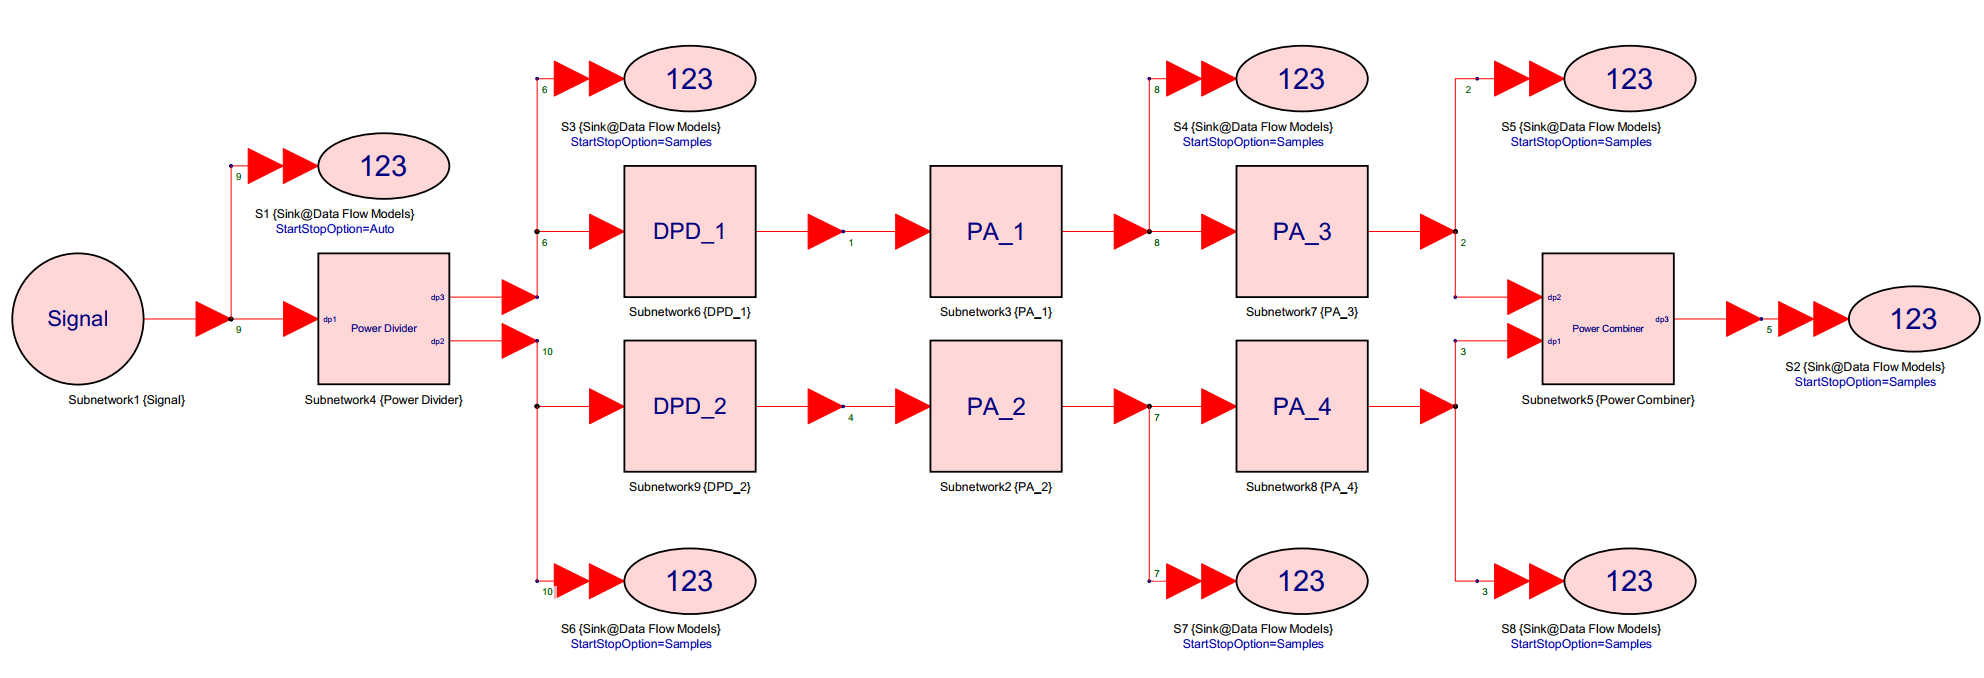

% 运行前请先将子文件夹添加到路径
clc; 

## -----------------------------Original System----------------------------

此模型是完全固定的！

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Original();
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
Original_output = Data_matrix(:,end-1) + 1i * Data_matrix(:,end); 
% 模型仿真
[U1,D1]=Power_Divider(Sys_input);
U2=PA_1(U1);
U3=PA_3(U2);
D2=PA_2(D1);
D3=PA_4(D2);
Original_output_sim=Power_Combiner(U3,D3);
% 性能评估
err=abs(Original_output_sim-Original_output) %模型本身的误差

err = 1.0e-13 *

    0.0037
    0.0030
    0.0057
    0.0049
    0.0051
    0.0050
    0.0098
    0.0063
    0.0109
    0.0111


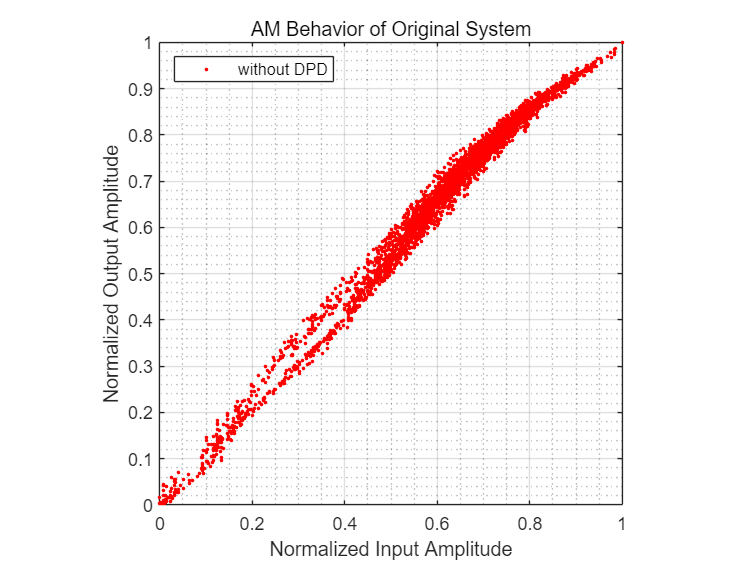

Plot_AM(Sys_input,Original_output_sim,'AM Behavior of Original System','without DPD');

nmse_sim= NMSE_dB(Sys_input,Original_output_sim);
nmse_act = NMSE_dB(Sys_input,Original_output);
fprintf('不使用DPD，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

不使用DPD，系统的NMSE仿真结果为 -16.688242 dB


fprintf('不使用DPD，系统的NMSE实测结果为 %f dB\n', nmse_act);

不使用DPD，系统的NMSE实测结果为 -16.688242 dB


## -----------------------------Model A2 System----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Original();
% 根据需要选取原始数据
Sys_x_i=Data_matrix(:,1);Sys_x_q=Data_matrix(:,2);
Sys_y_i=Data_matrix(:,15);Sys_y_q=Data_matrix(:,16);
Sys_input = Sys_x_i + 1i * Sys_x_q;
Sys_output = Sys_y_i + 1i * Sys_y_q;
PA1_x_i=Data_matrix(:,3);PA1_x_q=Data_matrix(:,4);
PA3_y_i=Data_matrix(:,11);PA3_y_q=Data_matrix(:,12);
PA1_input = PA1_x_i + 1i * PA1_x_q;
PA3_output = PA3_y_i + 1i * PA3_y_q;
PA2_x_i=Data_matrix(:,5);PA2_x_q=Data_matrix(:,6);
PA4_y_i=Data_matrix(:,13);PA4_y_q=Data_matrix(:,14);
PA2_input = PA2_x_i + 1i * PA2_x_q;
PA4_output = PA4_y_i + 1i * PA4_y_q;

## 训练上路(训练一次即可)

M=7; % Memory Depth
X = zeros(2*(M + 1), dim-M);
for j = 1:length(PA3_y_i) - M
    X(:, j) = [PA3_y_i(j : j + M); PA3_y_q(j : j + M)];
end
Y = [PA1_x_i(M + 1 : end)'; PA1_x_q(M + 1 : end)'];
net = feedforwardnet(10);% 神经元数量

%%%%%%%%%%%%%%%%%%%%%%%%%% 1：FNN %%%%%%%%%%%%%%%%%%%%%%%%%%
FNN = train(net, X, Y);
save('Algorithm_B\Alg_Upper.mat', 'FNN','-append');

## 训练下路(训练一次即可)

M=7; % Memory Depth
X = zeros(2*(M + 1), dim-M);
for j = 1:length(PA4_y_i) - M
    X(:, j) = [PA4_y_i(j : j + M); PA4_y_q(j : j + M)];
end
Y = [PA2_x_i(M + 1 : end)'; PA2_x_q(M + 1 : end)'];
net = feedforwardnet(10);% 神经元数量

%%%%%%%%%%%%%%%%%%%%%%%%%% 1：FNN %%%%%%%%%%%%%%%%%%%%%%%%%%
FNN = train(net, X, Y);
save('Algorithm_B\Alg_Lower.mat', 'FNN','-append');

## Model Test

% 参数需要保持一致
M = 7;
% 系统模拟
[S_U1,S_D1]=Power_Divider(Sys_input);
S_U1_DPD= DPD(S_U1,M,1,'Algorithm_B\Alg_Upper.mat');% input,记忆深度,不同算法,不同位置
S_U2    = PA_1(S_U1_DPD);
S_U3    = PA_3(S_U2);
S_D1_DPD= DPD(S_D1,M,1,'Algorithm_B\Alg_Lower.mat');% input,记忆深度,不同算法,不同位置
S_D2    = PA_2(S_D1_DPD);
S_D3    = PA_4(S_D2);
Sys_output_sim=Power_Combiner(S_U3,S_D3);

% 性能评估
nmse_DPD=Get_nmse_DPD(Sys_output_sim,Sys_output);
fprintf('单级DPD的相对NMSE为 %f dB\n', nmse_DPD);

单级DPD的相对NMSE为 -18.024608 dB


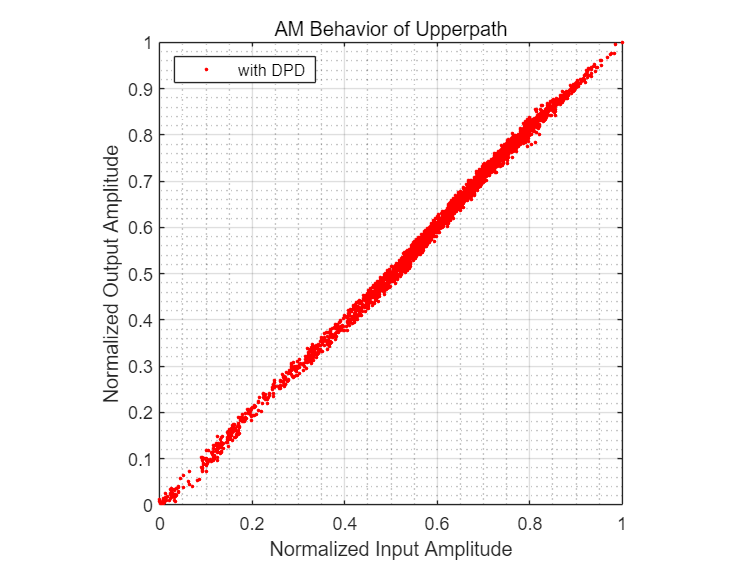

Plot_AM(S_U1,S_U3,'AM Behavior of Upperpath','with DPD');

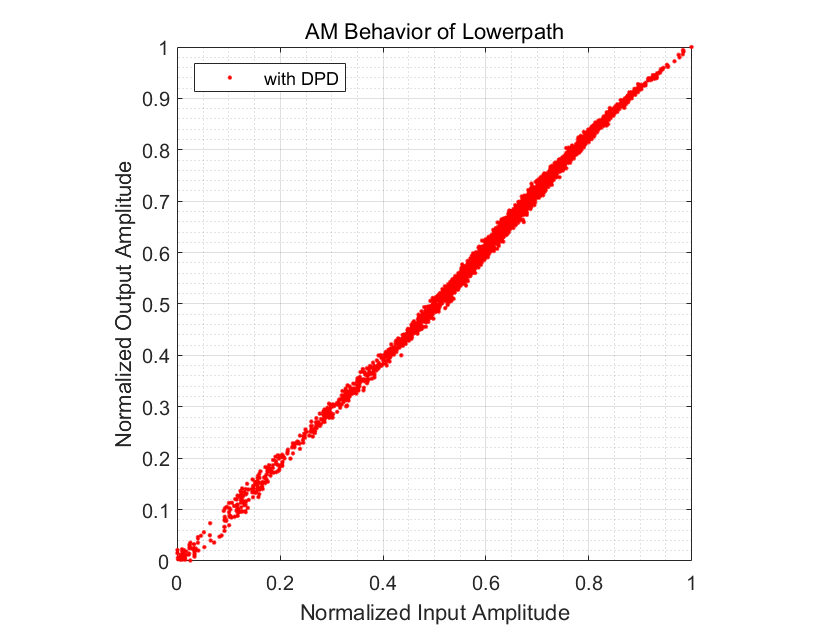

Plot_AM(S_D1,S_D3,'AM Behavior of Lowerpath','with DPD');

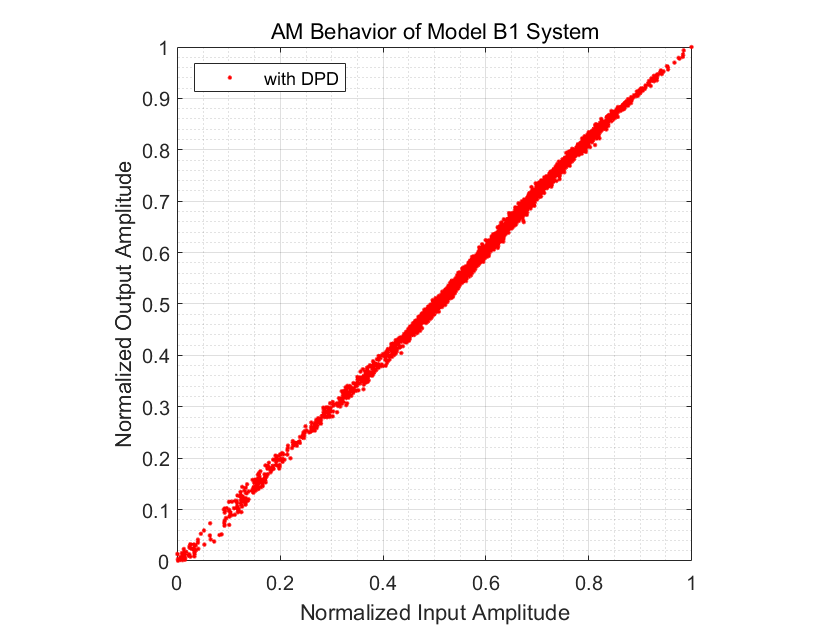

Plot_AM(Sys_input,Sys_output_sim,'AM Behavior of Model B1 System','with DPD');

nmse_sim= NMSE_dB(Sys_input,Sys_output_sim);
fprintf('使用Model A2，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

使用Model A2，系统的NMSE仿真结果为 -28.809893 dB
